# Machine Learning: Programming Exercise 5

## Regularized Linear Regression and Bias vs. Variance

In this exercise, you will implement regularized linear regression and use it to study models with different bias-variance properties.

### Files needed for this exercise

- `ex5.mlx` - MATLAB Live Script that steps you through the exercise

- `ex5data1.mat` - Dataset

- `submit.m` - Submission script that sends your solutions to our servers

- `featureNormalize.m` - Feature normalization function

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `plotFit.m` - Plot a polynomial fit

- `trainLinearReg.m` - Trains linear regression using your cost function

- *`linearRegCostFunction.m` - Regularized linear regression cost function

- `*learningCurve.m` - Generates a learning curve

- *`polyFeatures.m` - Maps data into polynomial feature space

- *`validationCurve.m` - Generates a cross validation curve

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex5' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Regularized Linear Regression

In the first half of the exercise, you will implement regularized linear regression to predict the amount of water flowing out of a dam using the change of water level in a reservoir. In the next half, you will go through some diagnostics of debugging learning algorithms and examine the effects of bias vs. variance.

### 1.1 Visualizing the dataset

We will begin by visualizing the dataset containing historical records on the change in the water level, $x$, and the amount of water flowing out of the dam, $y$. This dataset is divided into three parts:

- A **training** set that your model will learn on: `X, y`

- A **cross validation** set for determining the regularization parameter: `Xval, yval`

- A **test** set for evaluating performance. These are 'unseen' examples which your model did not see during training:` Xtest, ytest`

The code below will plot the training data (Figure 1). In the following parts, you will implement linear regression and use that to fit a straight line to the data and plot learning curves. Following that, you will implement polynomial regression to find a better fit to the data.

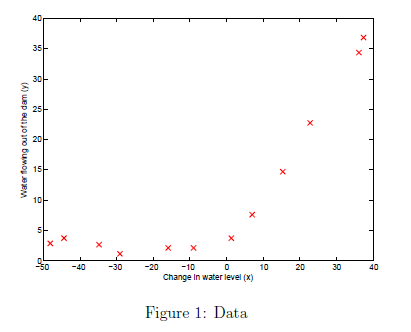

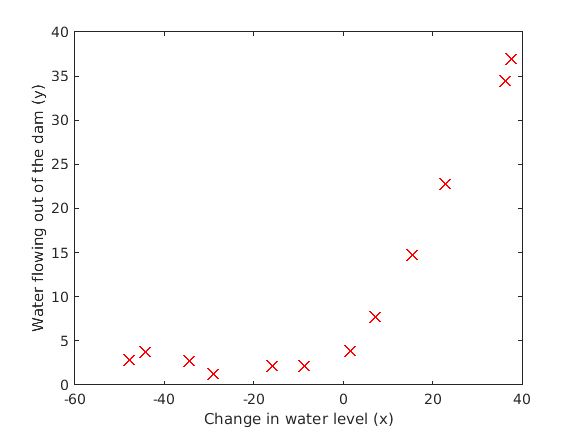

% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment

load ('ex5data1.mat');
% m = Number of examples
m = size(X, 1);

% Plot training data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');

J = 303.9932

ylabel('Water flowing out of the dam (y)');

Cost at theta = [1 ; 1]: 303.993192

### 1.2 Regularized linear regression cost function

Recall that regularized linear regression has the following cost function:


$$J\left(\theta \right)=\frac{1}{2m}\left(\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right)+\frac{\;\lambda }{2m}\left(\sum_{j=1}^n \theta_j^2 \right)$$


where $\lambda$ is a regularization parameter which controls the degree of regularization (thus, helps preventing overtting). The regularization term puts a penalty on the overall cost $J$. As the magnitudes of the model parameters $\theta_j$ increase, the penalty increases as well. Note that you should not regularize the $\theta_0$ term. (In MATLAB, the $\theta_0$ term is represented as `theta(1)` since indexing in MATLAB starts from 1).

    You should now complete the code in the file `linearRegCostFunction.m`. Your task is to write a function to calculate the regularized linear regression cost function. If possible, try to vectorize your code and avoid writing loops. When you are finished, the code below will run your cost function using `theta` initialized at `[1; 1]`. You should expect to see an output of 303.993.

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Cost at theta = [1 ; 1]: %f', J);

J = 303.9932

grad =   -15.3030
  598.1674


grad =   -15.3030
  598.2507


Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.3 Regularized linear regression gradient

Correspondingly, the partial derivative of regularized linear regression's cost for $\theta_j$ is defined as


$$\begin{array}{l}
\frac{\partial J\left(\theta \right)}{\partial \theta_0 }=\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\mathrm{for}\;\;j=0\\
\frac{\partial J\left(\theta \right)}{\partial \theta_j }=\left(\frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\;\;\mathrm{for}\;\;j>0
\end{array}$$


In `linearRegCostFunction.m`, add code to calculate the gradient, returning it in the variable `grad`. When you are finished, the code below will run your gradient function using theta initialized at [1; 1]. You should expect to see a gradient of [-15.30; 598.250].

[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);
fprintf('Gradient at theta = [1 ; 1]:  [%f; %f] \n',grad(1), grad(2));

J = 140.9541

grad =   -11.2176
 -245.6520


grad =   -11.2176
 -245.6520


J = 139.9611

grad =   -11.2381
 -242.2045


grad =   -11.2381
 -242.2045


J = 138.0172

grad =   -11.2790
 -235.3094


grad =   -11.2790
 -235.3094


J = 132.5213

grad =   -11.4018
 -214.6242


grad =   -11.4018
 -214.6242


J = 119.0579

grad =   -11.7704
 -152.5687


grad =   -11.7704
 -152.5687


J = 105.2435

grad =   -12.6798
    0.5790


grad =   -12.6798
    0.5790


Iteration     1 | Cost: 1.052435e+02


J = 87.3070

grad =   -11.2240
    0.5125


grad =   -11.2240
    0.5125


J = 57.9883

grad =    -8.3124
    0.3796


grad =    -8.3124
    0.3796


J = 22.3739

grad = 	1.0e+-10 *

   -0.0032
    0.4718


grad = 	1.0e+-10 *

   -0.0032
    0.4718


Iteration     2 | Cost: 2.237391e+01


J = 22.3739

grad = 	1.0e+-5 *

    0.0024
   -0.4120


grad = 	1.0e+-5 *

    0.0024
   -0.4120


J = 22.3739

grad = 	1.0e+-6 *

    0.0024
   -0.4119


grad = 	1.0e+-6 *

    0.0024
   -0.4119


J = 22.3739

grad = 	1.0e+-6 *

    0.0016
   -0.2746


grad = 	1.0e+-6 *

    0.0016
   -0.2746


J = 22.3739

grad = 	1.0e+-6 *

    0.0011
   -0.1830


grad = 	1.0e+-6 *

    0.0011
   -0.1830


J = 22.3739

grad = 	1.0e+-6 *

    0.0007
   -0.1220


grad = 	1.0e+-6 *

    0.0007
   -0.1220


J = 22.3739

grad = 	1.0e+-7 *

    0.0048
   -0.8131


grad = 	1.0e+-7 *

    0.0048
   -0.8131


J = 22.3739

grad = 	1.0e+-7 *

    0.0032
   -0.5419


grad = 	1.0e+-7 *

    0.0032
   -0.5419


J = 22.3739

grad = 	1.0e+-8 *

    0.0032
   -0.5376


grad = 	1.0e+-8 *

    0.0032
   -0.5376


J = 22.3739

grad = 	1.0e+-8 *

    0.0021
   -0.3560


grad = 	1.0e+-8 *

    0.0021
   -0.3560


J = 22.3739

grad = 	1.0e+-9 *

    0.0018
   -0.3136


grad = 	1.0e+-9 *

    0.0018
   -0.3136


J = 22.3739

grad = 	1.0e+-9 *

    0.0016
   -0.2775


grad = 	1.0e+-9 *

    0.0016
   -0.2775


J = 22.3739

grad = 	1.0e+-9 *

    0.0014
   -0.2451


grad = 	1.0e+-9 *

    0.0014
   -0.2451


J = 22.3739

grad = 	1.0e+-9 *

    0.0008
   -0.1379


grad = 	1.0e+-9 *

    0.0008
   -0.1379


J = 22.3739

grad = 	1.0e+-10 *

    0.0035
   -0.6493


grad = 	1.0e+-10 *

    0.0035
   -0.6493


J = 22.3739

grad = 	1.0e+-10 *

    0.0028
   -0.5374


grad = 	1.0e+-10 *

    0.0028
   -0.5374


J = 22.3739

grad = 	1.0e+-10 *

   -0.0026
    0.3710


grad = 	1.0e+-10 *

   -0.0026
    0.3710


J = 22.3739

grad = 2×1
	1.0e+-11 *

    0.0011
   -0.8328


grad = 2×1
	1.0e+-11 *

    0.0011
   -0.8328


Iteration     3 | Cost: 2.237391e+01


J = 22.3739

grad = 2×1
	1.0e+-9 *

   -0.0019
    0.3061


grad = 2×1
	1.0e+-9 *

   -0.0019
    0.3061


J = 22.3739

grad = 2×1
	1.0e+-9 *

   -0.0012
    0.1998


grad = 2×1
	1.0e+-9 *

   -0.0012
    0.1998


J = 22.3739

grad = 2×1
	1.0e+-9 *

   -0.0008
    0.1289


grad = 2×1
	1.0e+-9 *

   -0.0008
    0.1289


J = 22.3739

grad = 2×1
	1.0e+-10 *

   -0.0053
    0.8168


grad = 2×1
	1.0e+-10 *

   -0.0053
    0.8168


J = 22.3739

grad = 2×1
	1.0e+-10 *

   -0.0034
    0.5010


grad = 2×1
	1.0e+-10 *

   -0.0034
    0.5010


J = 22.3739

grad = 2×1
	1.0e+-10 *

   -0.0021
    0.2896


grad = 2×1
	1.0e+-10 *

   -0.0021
    0.2896


J = 22.3739

grad = 2×1
	1.0e+-10 *

   -0.0013
    0.1464


grad = 2×1
	1.0e+-10 *

   -0.0013
    0.1464


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0067
    0.4655


grad = 2×1
	1.0e+-11 *

   -0.0067
    0.4655


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0023
   -0.2708


grad = 2×1
	1.0e+-11 *

   -0.0023
   -0.2708


Iteration     4 | Cost: 2.237391e+01


J = 22.3739

grad = 2×1
	1.0e+-10 *

   -0.0013
    0.1457


grad = 2×1
	1.0e+-10 *

   -0.0013
    0.1457


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0088
    0.8247


grad = 2×1
	1.0e+-11 *

   -0.0088
    0.8247


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0029
   -0.1633


grad = 2×1
	1.0e+-11 *

   -0.0029
   -0.1633


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0059
    0.3326


grad = 2×1
	1.0e+-11 *

   -0.0059
    0.3326


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0047
    0.1251


grad = 2×1
	1.0e+-11 *

   -0.0047
    0.1251


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0031
   -0.1352


grad = 2×1
	1.0e+-11 *

   -0.0031
   -0.1352


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1576


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1576


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0031
   -0.1441


grad = 2×1
	1.0e+-11 *

   -0.0031
   -0.1441


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1550


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1550


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1550


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1550


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


grad = 2×1
	1.0e+-11 *

   -0.0030
   -0.1493


J = 22.3739

grad = 2×1
	1.0e+-8 *

   -0.0008
    0.1264


grad = 2×1
	1.0e+-8 *

   -0.0008
    0.1264


J = 22.3739

grad = 2×1
	1.0e+-8 *

   -0.0007
    0.1138


grad = 2×1
	1.0e+-8 *

   -0.0007
    0.1138


J = 22.3739

grad = 2×1
	1.0e+-8 *

   -0.0006
    0.1024


grad = 2×1
	1.0e+-8 *

   -0.0006
    0.1024


J = 22.3739

grad = 2×1
	1.0e+-10 *

   -0.0064
    0.9995


grad = 2×1
	1.0e+-10 *

   -0.0064
    0.9995


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0085
    0.7607


grad = 2×1
	1.0e+-11 *

   -0.0085
    0.7607


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0062
    0.3833


grad = 2×1
	1.0e+-11 *

   -0.0062
    0.3833


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0058
    0.3167


grad = 2×1
	1.0e+-11 *

   -0.0058
    0.3167


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0054
    0.2606


grad = 2×1
	1.0e+-11 *

   -0.0054
    0.2606


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0052
    0.2103


grad = 2×1
	1.0e+-11 *

   -0.0052
    0.2103


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0049
    0.1641


grad = 2×1
	1.0e+-11 *

   -0.0049
    0.1641


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2150


grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2150


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


J = 22.3739

grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


grad = 2×1
	1.0e+-11 *

   -0.0026
   -0.2214


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Fitting linear regression

Once your cost function and gradient are working correctly, the code in this section will run the code in `trainLinearReg.m` to compute the optimal values of $\theta$. This training function uses `fmincg` to optimize the cost function. In this part, we set regularization parameter $\lambda$ to zero. Because our current implementation of linear regression is trying to fit a 2-dimensional $\theta$, regularization will not be incredibly helpful for a $\theta$ of such low dimension. In the later parts of the exercise, you will be using polynomial regression with regularization.

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

    Finally, the code below should also plot the best fit line, resulting in an image similar to Figure 2. The best fit line tells us that the model is not a good fit to the data because the data has a nonlinear pattern. 

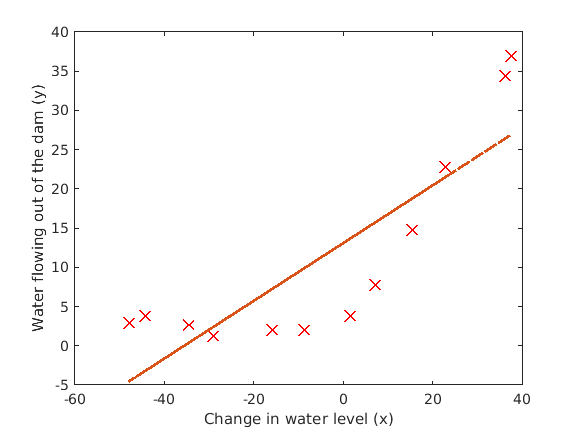

%  Plot fit over the data
figure;
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');

ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;

J = 2.2776

grad =    -2.1343
   34.0140


grad =    -2.1343
   34.0140


J = 1.3881

grad =    -1.6662
   26.5535


grad =    -1.6662
   26.5535


J = 0.2664

grad =    -0.7299
   11.6325


grad =    -0.7299
   11.6325


Iteration     1 | Cost: 2.663868e-01


J = 5.7008

grad =     3.3766
  -53.8125


grad =     3.3766
  -53.8125


J = 3.9443e-31

grad = 	1.0e+-13 *

   -0.0089
    0.1415


grad = 	1.0e+-13 *

   -0.0089
    0.1415


Iteration     2 | Cost: 3.944305e-31


J = 1.4389e-26

grad = 	1.0e+-11 *

    0.0170
   -0.2704


grad = 	1.0e+-11 *

    0.0170
   -0.2704


J = 1.3499e-28

grad = 	1.0e+-12 *

    0.0164
   -0.2619


grad = 	1.0e+-12 *

    0.0164
   -0.2619


J = 3.9443e-31

grad = 	1.0e+-13 *

    0.0089
   -0.1415


grad = 	1.0e+-13 *

    0.0089
   -0.1415


J = 0

grad =      0
     0


grad =      0
     0


Iteration     3 | Cost: 0.000000e+00


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad =      0
     0


grad =      0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 0

grad = 2×1
     0
     0


grad = 2×1
     0
     0


J = 205.1211

grad = 2×1
  -12.3370
 -367.6732


grad = 2×1
  -12.3370
 -367.6732


J = 1.4830

grad = 2×1
   -1.6538
   34.1090


grad = 2×1
   -1.6538
   34.1090


J = 0.7204

grad = 2×1
   -0.9935
   17.9472


grad = 2×1
   -0.9935
   17.9472


J = 0.4282

grad = 2×1
   -0.2598
   -0.0126


grad = 2×1
   -0.2598
   -0.0126


Iteration     1 | Cost: 4.282328e-01


J = 0.4161

grad = 2×1
   -0.2561
   -0.0124


grad = 2×1
   -0.2561
   -0.0124


J = 0.3923

grad = 2×1
   -0.2487
   -0.0121


grad = 2×1
   -0.2487
   -0.0121


J = 0.3252

grad = 2×1
   -0.2264
   -0.0110


grad = 2×1
   -0.2264
   -0.0110


J = 0.1616

grad = 2×1
   -0.1596
   -0.0077


grad = 2×1
   -0.1596
   -0.0077


J = 8.3323e-30

grad = 2×1
	1.0e+-13 *

    0.0377
   -0.9537


grad = 2×1
	1.0e+-13 *

    0.0377
   -0.9537


Iteration     2 | Cost: 8.332343e-30


J = 4.0363e-18

grad = 2×1
	1.0e+-7 *

   -0.0273
    0.6675


grad = 2×1
	1.0e+-7 *

   -0.0273
    0.6675


J = 4.0362e-20

grad = 2×1
	1.0e+-8 *

   -0.0273
    0.6675


grad = 2×1
	1.0e+-8 *

   -0.0273
    0.6675


J = 4.0351e-22

grad = 2×1
	1.0e+-9 *

   -0.0273
    0.6674


grad = 2×1
	1.0e+-9 *

   -0.0273
    0.6674


J = 4.0248e-24

grad = 2×1
	1.0e+-10 *

   -0.0272
    0.6665


grad = 2×1
	1.0e+-10 *

   -0.0272
    0.6665


J = 3.9224e-26

grad = 2×1
	1.0e+-11 *

   -0.0269
    0.6580


grad = 2×1
	1.0e+-11 *

   -0.0269
    0.6580


J = 2.9548e-28

grad = 2×1
	1.0e+-12 *

   -0.0233
    0.5711


grad = 2×1
	1.0e+-12 *

   -0.0233
    0.5711


J = 9.8608e-32

grad = 2×1
	1.0e+-14 *

         0
   -0.2935


grad = 2×1
	1.0e+-14 *

         0
   -0.2935


Iteration     3 | Cost: 9.860761e-32


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 4.9304e-32

grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


grad = 2×1
	1.0e+-14 *

   -0.0222
    0.3539


J = 3.4719e-27

grad = 2×1
	1.0e+-11 *

    0.0080
   -0.1958


grad = 2×1
	1.0e+-11 *

    0.0080
   -0.1958


J = 3.6731e-29

grad = 2×1
	1.0e+-12 *

    0.0082
   -0.2014


grad = 2×1
	1.0e+-12 *

    0.0082
   -0.2014


J = 8.3816e-31

grad = 2×1
	1.0e+-13 *

    0.0111
   -0.2943


grad = 2×1
	1.0e+-13 *

    0.0111
   -0.2943


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 1.9722e-31

grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


grad = 2×1
	1.0e+-13 *

    0.0044
   -0.1295


J = 9.8608e-32

grad = 2×1
	1.0e+-14 *

         0
   -0.2935


grad = 2×1
	1.0e+-14 *

         0
   -0.2935


J = 110.3004

grad = 2×1
   -9.9193
 -197.7035


grad = 2×1
   -9.9193
 -197.7035


J = 197.7467

grad = 2×1
  -12.5556
 -391.7409


grad = 2×1
  -12.5556
 -391.7409


J = 196.7493

grad = 2×1
  -12.5630
 -389.6896


grad = 2×1
  -12.5630
 -389.6896


J = 194.7703

grad = 2×1
  -12.5780
 -385.5869


grad = 2×1
  -12.5780
 -385.5869


J = 188.9586

grad = 2×1
  -12.6229
 -373.2788


grad = 2×1
  -12.6229
 -373.2788


J = 172.6534

grad = 2×1
  -12.7576
 -336.3547


grad = 2×1
  -12.7576
 -336.3547


J = 133.9057

grad = 2×1
  -13.1617
 -225.5823


grad = 2×1
  -13.1617
 -225.5823


J = 102.1540

grad = 2×1
  -13.9863
    0.4483


grad = 2×1
  -13.9863
    0.4483


Iteration     1 | Cost: 1.021540e+02


J = 79.2852

grad = 2×1
  -12.2625
    0.3930


grad = 2×1
  -12.2625
    0.3930


J = 42.5587

grad = 2×1
   -8.8149
    0.2825


grad = 2×1
   -8.8149
    0.2825


J = 3.2866

grad = 2×1
	1.0e+-10 *

   -0.0019
    0.1644


grad = 2×1
	1.0e+-10 *

   -0.0019
    0.1644


Iteration     2 | Cost: 3.286595e+00


J = 3.2866

grad = 2×1
	1.0e+-5 *

    0.0005
   -0.1336


grad = 2×1
	1.0e+-5 *

    0.0005
   -0.1336


J = 3.2866

grad = 2×1
	1.0e+-5 *

    0.0004
   -0.1089


grad = 2×1
	1.0e+-5 *

    0.0004
   -0.1089


J = 3.2866

grad = 2×1
	1.0e+-6 *

    0.0004
   -0.1089


grad = 2×1
	1.0e+-6 *

    0.0004
   -0.1089


J = 3.2866

grad = 2×1
	1.0e+-7 *

    0.0036
   -0.9796


grad = 2×1
	1.0e+-7 *

    0.0036
   -0.9796


J = 3.2866

grad = 2×1
	1.0e+-7 *

    0.0032
   -0.8817


grad = 2×1
	1.0e+-7 *

    0.0032
   -0.8817


J = 3.2866

grad = 2×1
	1.0e+-7 *

    0.0029
   -0.7935


grad = 2×1
	1.0e+-7 *

    0.0029
   -0.7935


J = 3.2866

grad = 2×1
	1.0e+-7 *

    0.0026
   -0.7141


grad = 2×1
	1.0e+-7 *

    0.0026
   -0.7141


J = 3.2866

grad = 2×1
	1.0e+-7 *

    0.0023
   -0.6427


grad = 2×1
	1.0e+-7 *

    0.0023
   -0.6427


J = 3.2866

grad = 2×1
	1.0e+-7 *

    0.0021
   -0.5784


grad = 2×1
	1.0e+-7 *

    0.0021
   -0.5784


J = 3.2866

grad = 2×1
	1.0e+-7 *

    0.0019
   -0.5205


grad = 2×1
	1.0e+-7 *

    0.0019
   -0.5205


J = 3.2866

grad = 2×1
	1.0e+-7 *

    0.0017
   -0.4685


grad = 2×1
	1.0e+-7 *

    0.0017
   -0.4685


J = 3.2866

grad = 2×1
	1.0e+-8 *

    0.0017
   -0.4670


grad = 2×1
	1.0e+-8 *

    0.0017
   -0.4670


J = 3.2866

grad = 2×1
	1.0e+-8 *

    0.0015
   -0.4202


grad = 2×1
	1.0e+-8 *

    0.0015
   -0.4202


J = 3.2866

grad = 2×1
	1.0e+-8 *

    0.0014
   -0.3780


grad = 2×1
	1.0e+-8 *

    0.0014
   -0.3780


J = 3.2866

grad = 2×1
	1.0e+-8 *

    0.0012
   -0.3400


grad = 2×1
	1.0e+-8 *

    0.0012
   -0.3400


J = 3.2866

grad = 2×1
	1.0e+-8 *

    0.0011
   -0.3059


grad = 2×1
	1.0e+-8 *

    0.0011
   -0.3059


J = 3.2866

grad = 2×1
	1.0e+-8 *

    0.0007
   -0.2031


grad = 2×1
	1.0e+-8 *

    0.0007
   -0.2031


J = 3.2866

grad = 2×1
	1.0e+-8 *

    0.0007
   -0.1826


grad = 2×1
	1.0e+-8 *

    0.0007
   -0.1826


J = 3.2866

grad = 2×1
	1.0e+-8 *

    0.0006
   -0.1642


grad = 2×1
	1.0e+-8 *

    0.0006
   -0.1642


J = 3.2866

grad = 2×1
	1.0e+-8 *

    0.0005
   -0.1476


grad = 2×1
	1.0e+-8 *

    0.0005
   -0.1476


J = 3.2866

grad = 2×1
	1.0e+-9 *

    0.0004
   -0.1330


grad = 2×1
	1.0e+-9 *

    0.0004
   -0.1330


J = 3.2866

grad = 2×1
	1.0e+-6 *

   -0.0004
    0.1070


grad = 2×1
	1.0e+-6 *

   -0.0004
    0.1070


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0036
    0.9628


grad = 2×1
	1.0e+-7 *

   -0.0036
    0.9628


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0032
    0.8666


grad = 2×1
	1.0e+-7 *

   -0.0032
    0.8666


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0029
    0.7799


grad = 2×1
	1.0e+-7 *

   -0.0029
    0.7799


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0026
    0.7020


grad = 2×1
	1.0e+-7 *

   -0.0026
    0.7020


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0023
    0.6318


grad = 2×1
	1.0e+-7 *

   -0.0023
    0.6318


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0021
    0.5686


grad = 2×1
	1.0e+-7 *

   -0.0021
    0.5686


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0019
    0.5118


grad = 2×1
	1.0e+-7 *

   -0.0019
    0.5118


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0017
    0.4606


grad = 2×1
	1.0e+-7 *

   -0.0017
    0.4606


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0015
    0.4146


grad = 2×1
	1.0e+-7 *

   -0.0015
    0.4146


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0014
    0.3731


grad = 2×1
	1.0e+-7 *

   -0.0014
    0.3731


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0012
    0.3358


grad = 2×1
	1.0e+-7 *

   -0.0012
    0.3358


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0008
    0.2237


grad = 2×1
	1.0e+-7 *

   -0.0008
    0.2237


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0007
    0.2014


grad = 2×1
	1.0e+-7 *

   -0.0007
    0.2014


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0007
    0.1812


grad = 2×1
	1.0e+-7 *

   -0.0007
    0.1812


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0006
    0.1631


grad = 2×1
	1.0e+-7 *

   -0.0006
    0.1631


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0005
    0.1468


grad = 2×1
	1.0e+-7 *

   -0.0005
    0.1468


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0005
    0.1322


grad = 2×1
	1.0e+-7 *

   -0.0005
    0.1322


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0004
    0.1190


grad = 2×1
	1.0e+-7 *

   -0.0004
    0.1190


J = 3.2866

grad = 2×1
	1.0e+-7 *

   -0.0004
    0.1071


grad = 2×1
	1.0e+-7 *

   -0.0004
    0.1071


J = 3.2866

grad = 2×1
	1.0e+-8 *

   -0.0036
    0.9640


grad = 2×1
	1.0e+-8 *

   -0.0036
    0.9640


J = 3.2866

grad = 2×1
	1.0e+-10 *

   -0.0019
    0.1644


grad = 2×1
	1.0e+-10 *

   -0.0019
    0.1644


J = 45.0102

grad = 2×1
   -1.0197
  172.4830


grad = 2×1
   -1.0197
  172.4830


J = 317.9394

grad = 2×1
  -18.6262
 -639.0896


grad = 2×1
  -18.6262
 -639.0896


J = 316.9406

grad = 2×1
  -18.6149
 -637.5965


grad = 2×1
  -18.6149
 -637.5965


J = 314.9499

grad = 2×1
  -18.5925
 -634.6104


grad = 2×1
  -18.5925
 -634.6104


J = 309.0340

grad = 2×1
  -18.5252
 -625.6520


grad = 2×1
  -18.5252
 -625.6520


J = 291.7905

grad = 2×1
  -18.3232
 -598.7768


grad = 2×1
  -18.3232
 -598.7768


J = 244.5988

grad = 2×1
  -17.7173
 -518.1514


grad = 2×1
  -17.7173
 -518.1514


J = 143.8726

grad = 2×1
  -15.8995
 -276.2751


grad = 2×1
  -15.8995
 -276.2751


Iteration     1 | Cost: 1.438726e+02


J = 266.7254

grad = 2×1
   -9.5636
  559.5656


grad = 2×1
   -9.5636
  559.5656


J = 103.5224

grad = 2×1
  -13.7954
    1.3080


grad = 2×1
  -13.7954
    1.3080


Iteration     2 | Cost: 1.035224e+02


J = 75.3672

grad = 2×1
  -11.7967
 -157.2596


grad = 2×1
  -11.7967
 -157.2596


Iteration     3 | Cost: 7.536716e+01


J = 37.8849

grad = 2×1
   -8.3702
  -55.1758


grad = 2×1
   -8.3702
  -55.1758


J = 16.1542

grad = 2×1
   -3.1045
  101.7042


grad = 2×1
   -3.1045
  101.7042


Iteration     4 | Cost: 1.615422e+01


J = 177.4398

grad = 2×1
   15.2680
 -214.7555


grad = 2×1
   15.2680
 -214.7555


J = 3.6193

grad = 2×1
    0.7849
   34.7119


grad = 2×1
    0.7849
   34.7119


Iteration     5 | Cost: 3.619255e+00


J = 180.8799

grad = 2×1
  -11.8838
 -525.5837


grad = 2×1
  -11.8838
 -525.5837


J = 3.1356

grad = 2×1
   -0.4820
  -21.3176


grad = 2×1
   -0.4820
  -21.3176


J = 2.8519

grad = 2×1
   -0.0854
   -3.7767


grad = 2×1
   -0.0854
   -3.7767


Iteration     6 | Cost: 2.851871e+00


J = 100.3273

grad = 2×1
    3.1827
  431.4575


grad = 2×1
    3.1827
  431.4575


J = 3.6716

grad = 2×1
    0.2414
   39.7467


grad = 2×1
    0.2414
   39.7467


J = 2.8446

grad = 2×1
   -0.0527
    0.5756


grad = 2×1
   -0.0527
    0.5756


Iteration     7 | Cost: 2.844569e+00


J = 3.2470

grad = 2×1
   -0.2621
  -27.7319


grad = 2×1
   -0.2621
  -27.7319


J = 2.8470

grad = 2×1
   -0.0736
   -2.2551


grad = 2×1
   -0.0736
   -2.2551


J = 2.8444

grad = 2×1
   -0.0570
   -0.0052


grad = 2×1
   -0.0570
   -0.0052


Iteration     8 | Cost: 2.844392e+00


J = 2.8441

grad = 2×1
   -0.0512
   -0.0047


grad = 2×1
   -0.0512
   -0.0047


J = 2.8435

grad = 2×1
   -0.0397
   -0.0036


grad = 2×1
   -0.0397
   -0.0036


J = 2.8427

grad = 2×1
   -0.0052
   -0.0005


grad = 2×1
   -0.0052
   -0.0005


Iteration     9 | Cost: 2.842692e+00


J = 3.9670

grad = 2×1
    0.3797
   46.3233


grad = 2×1
    0.3797
   46.3233


J = 2.8539

grad = 2×1
    0.0333
    4.6319


grad = 2×1
    0.0333
    4.6319


J = 2.8428

grad = 2×1
   -0.0013
    0.4628


grad = 2×1
   -0.0013
    0.4628


J = 2.8427

grad = 2×1
   -0.0048
    0.0459


grad = 2×1
   -0.0048
    0.0459


J = 2.8427

grad = 2×1
   -0.0051
    0.0043


grad = 2×1
   -0.0051
    0.0043


Iteration    10 | Cost: 2.842692e+00


J = 2.8427

grad = 2×1
   -0.0051
    0.0023


grad = 2×1
   -0.0051
    0.0023


J = 2.8427

grad = 2×1
   -0.0051
   -0.0016


grad = 2×1
   -0.0051
   -0.0016


Iteration    11 | Cost: 2.842692e+00


J = 2.8427

grad = 2×1
   -0.0051
    0.0000


grad = 2×1
   -0.0051
    0.0000


J = 2.8427

grad = 2×1
   -0.0051
    0.0032


grad = 2×1
   -0.0051
    0.0032


J = 2.8427

grad = 2×1
   -0.0049
    0.0129


grad = 2×1
   -0.0049
    0.0129


J = 2.8427

grad = 2×1
   -0.0045
    0.0379


grad = 2×1
   -0.0045
    0.0379


Iteration    12 | Cost: 2.842691e+00


J = 2.8427

grad = 2×1
   -0.0041
    0.0419


grad = 2×1
   -0.0041
    0.0419


J = 2.8427

grad = 2×1
   -0.0033
    0.0498


grad = 2×1
   -0.0033
    0.0498


J = 2.8427

grad = 2×1
   -0.0009
    0.0735


grad = 2×1
   -0.0009
    0.0735


Iteration    13 | Cost: 2.842682e+00


J = 2.8427

grad = 2×1
   -0.0007
   -0.0988


grad = 2×1
   -0.0007
   -0.0988


J = 2.8427

grad = 2×1
   -0.0008
   -0.0069


grad = 2×1
   -0.0008
   -0.0069


Iteration    14 | Cost: 2.842678e+00


J = 2.8427

grad = 2×1
    0.0064
   -0.0066


grad = 2×1
    0.0064
   -0.0066


J = 2.8427

grad = 2×1
   -0.0001
   -0.0068


grad = 2×1
   -0.0001
   -0.0068


Iteration    15 | Cost: 2.842678e+00


J = 2.8427

grad = 2×1
    0.0006
    0.0836


grad = 2×1
    0.0006
    0.0836


J = 2.8427

grad = 2×1
    0.0000
    0.0022


grad = 2×1
    0.0000
    0.0022


Iteration    16 | Cost: 2.842678e+00


J = 2.8427

grad = 2×1
   -0.0002
   -0.0260


grad = 2×1
   -0.0002
   -0.0260


J = 2.8427

grad = 2×1
	1.0e+-3 *

   -0.0048
   -0.6282


grad = 2×1
	1.0e+-3 *

   -0.0048
   -0.6282


Iteration    17 | Cost: 2.842678e+00


J = 2.8427

grad = 2×1
    0.0001
    0.0092


grad = 2×1
    0.0001
    0.0092


J = 2.8427

grad = 2×1
	1.0e+-3 *

    0.0026
    0.3579


grad = 2×1
	1.0e+-3 *

    0.0026
    0.3579


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


Iteration    18 | Cost: 2.842678e+00


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1046
    0.0046


grad = 2×1
	1.0e+-6 *

   -0.1046
    0.0046


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1131
    0.0046


grad = 2×1
	1.0e+-6 *

   -0.1131
    0.0046


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1158
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1158
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


grad = 2×1
	1.0e+-6 *

   -0.1161
    0.0047


J = 2.8427

grad = 2×1
	1.0e+-5 *

   -0.0033
   -0.3619


grad = 2×1
	1.0e+-5 *

   -0.0033
   -0.3619


J = 2.8427

grad = 2×1
	1.0e+-5 *

   -0.0081
   -0.1526


grad = 2×1
	1.0e+-5 *

   -0.0081
   -0.1526


Iteration    20 | Cost: 2.842678e+00


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0284
    0.2102


grad = 2×1
	1.0e+-6 *

   -0.0284
    0.2102


Iteration    21 | Cost: 2.842678e+00


J = 2.8427

grad = 2×1
	1.0e+-5 *

    0.0099
   -0.3463


grad = 2×1
	1.0e+-5 *

    0.0099
   -0.3463


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0079
   -0.3797


grad = 2×1
	1.0e+-6 *

   -0.0079
   -0.3797


Iteration    22 | Cost: 2.842678e+00


J = 2.8427

grad = 2×1
	1.0e+-6 *

    0.1557
   -0.2801


grad = 2×1
	1.0e+-6 *

    0.1557
   -0.2801


J = 2.8427

grad = 2×1
	1.0e+-6 *

    0.0084
   -0.3698


grad = 2×1
	1.0e+-6 *

    0.0084
   -0.3698


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0061
   -0.3786


grad = 2×1
	1.0e+-6 *

   -0.0061
   -0.3786


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


grad = 2×1
	1.0e+-6 *

   -0.0063
   -0.3787


J = 2.8427

grad = 2×1
	1.0e+-3 *

    0.0027
    0.3613


grad = 2×1
	1.0e+-3 *

    0.0027
    0.3613


J = 2.8427

grad = 2×1
	1.0e+-4 *

    0.0026
    0.3579


grad = 2×1
	1.0e+-4 *

    0.0026
    0.3579


J = 2.8427

grad = 2×1
	1.0e+-5 *

    0.0019
    0.3237


grad = 2×1
	1.0e+-5 *

    0.0019
    0.3237


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0522
   -0.1807


grad = 2×1
	1.0e+-7 *

   -0.0522
   -0.1807


Iteration    24 | Cost: 2.842678e+00


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0412
    0.6680


grad = 2×1
	1.0e+-7 *

   -0.0412
    0.6680


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0469
    0.2311


grad = 2×1
	1.0e+-7 *

   -0.0469
    0.2311


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1395


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1395


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.4928
    0.4581


grad = 2×1
	1.0e+-8 *

   -0.4928
    0.4581


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0514
   -0.1210


grad = 2×1
	1.0e+-7 *

   -0.0514
   -0.1210


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0516
   -0.1293


grad = 2×1
	1.0e+-7 *

   -0.0516
   -0.1293


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1368


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1368


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


grad = 2×1
	1.0e+-7 *

   -0.0517
   -0.1376


J = 2.8427

grad = 2×1
	1.0e+-4 *

    0.0010
    0.1316


grad = 2×1
	1.0e+-4 *

    0.0010
    0.1316


J = 2.8427

grad = 2×1
	1.0e+-5 *

    0.0005
    0.1300


grad = 2×1
	1.0e+-5 *

    0.0005
    0.1300


J = 2.8427

grad = 2×1
	1.0e+-6 *

   -0.0042
    0.1137


grad = 2×1
	1.0e+-6 *

   -0.0042
    0.1137


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0456
    0.6662


grad = 2×1
	1.0e+-7 *

   -0.0456
    0.6662


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0486
    0.2851


grad = 2×1
	1.0e+-7 *

   -0.0486
    0.2851


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0489
    0.2470


grad = 2×1
	1.0e+-7 *

   -0.0489
    0.2470


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5129
   -0.6169


grad = 2×1
	1.0e+-8 *

   -0.5129
   -0.6169


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5153
   -0.9256


grad = 2×1
	1.0e+-8 *

   -0.5153
   -0.9256


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5155
   -0.9565


grad = 2×1
	1.0e+-8 *

   -0.5155
   -0.9565


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9595


grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9595


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


J = 2.8427

grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


grad = 2×1
	1.0e+-8 *

   -0.5156
   -0.9599


J = 2.8427

grad = 2×1
	1.0e+-7 *

   -0.0522
   -0.1807


grad = 2×1
	1.0e+-7 *

   -0.0522
   -0.1807


J = 48.3689

grad = 2×1
   -0.6376
  188.9972


grad = 2×1
   -0.6376
  188.9972


J = 255.1405

grad = 2×1
  -15.4627
 -484.2725


grad = 2×1
  -15.4627
 -484.2725


J = 254.1432

grad = 2×1
  -15.4707
 -481.7442


grad = 2×1
  -15.4707
 -481.7442


J = 252.1640

grad = 2×1
  -15.4866
 -476.6876


grad = 2×1
  -15.4866
 -476.6876


J = 246.3518

grad = 2×1
  -15.5344
 -461.5176


grad = 2×1
  -15.5344
 -461.5176


J = 230.0415

grad = 2×1
  -15.6778
 -416.0078


grad = 2×1
  -15.6778
 -416.0078


J = 191.2487

grad = 2×1
  -16.1079
 -279.4784


grad = 2×1
  -16.1079
 -279.4784


J = 159.2641

grad = 2×1
  -16.9901
    0.5425


grad = 2×1
  -16.9901
    0.5425


Iteration     1 | Cost: 1.592641e+02


J = 136.6149

grad = 2×1
  -15.6179
    0.4987


grad = 2×1
  -15.6179
    0.4987


J = 97.0355

grad = 2×1
  -12.8733
    0.4110


grad = 2×1
  -12.8733
    0.4110


J = 24.0497

grad = 2×1
   -4.6396
    0.1481


grad = 2×1
   -4.6396
    0.1481


Iteration     2 | Cost: 2.404966e+01


J = 2.2005e+04

grad = 2×1
	1.0e+03 *

    0.0633
   -7.2034


grad = 2×1
	1.0e+03 *

    0.0633
   -7.2034


J = 224.7448

grad = 2×1
    2.1521
 -720.2100


grad = 2×1
    2.1521
 -720.2100


J = 24.1448

grad = 2×1
   -3.9604
  -71.8877


grad = 2×1
   -3.9604
  -71.8877


J = 23.5414

grad = 2×1
   -4.3146
  -34.3255


grad = 2×1
   -4.3146
  -34.3255


Iteration     3 | Cost: 2.354137e+01


J = 22.8116

grad = 2×1
   -4.3368
   -7.8988


grad = 2×1
   -4.3368
   -7.8988


Iteration     4 | Cost: 2.281160e+01


J = 27.7690

grad = 2×1
   -4.6675
  113.1052


grad = 2×1
   -4.6675
  113.1052


J = 22.7697

grad = 2×1
   -4.3699
    4.2016


grad = 2×1
   -4.3699
    4.2016


Iteration     5 | Cost: 2.276969e+01


J = 22.6728

grad = 2×1
   -4.3547
    7.4976


grad = 2×1
   -4.3547
    7.4976


J = 22.5076

grad = 2×1
   -4.3244
   14.0896


grad = 2×1
   -4.3244
   14.0896


J = 22.2406

grad = 2×1
   -4.2336
   33.8656


grad = 2×1
   -4.2336
   33.8656


Iteration     6 | Cost: 2.224060e+01


J = 21.3947

grad = 2×1
   -4.0560
   21.8261


grad = 2×1
   -4.0560
   21.8261


J = 20.1165

grad = 2×1
   -3.7008
   -2.2531


grad = 2×1
   -3.7008
   -2.2531


J = 19.2061

grad = 2×1
   -3.0554
  -45.9992


grad = 2×1
   -3.0554
  -45.9992


Iteration     7 | Cost: 1.920606e+01


J = 14.7529

grad = 2×1
   -1.3156
  -37.0210


grad = 2×1
   -1.3156
  -37.0210


Iteration     8 | Cost: 1.475292e+01


J = 29.2721

grad = 2×1
   -2.5074
  187.0033


grad = 2×1
   -2.5074
  187.0033


J = 14.3057

grad = 2×1
   -1.4912
   -4.0016


grad = 2×1
   -1.4912
   -4.0016


Iteration     9 | Cost: 1.430565e+01


J = 13.8888

grad = 2×1
   -1.0569
   24.7737


grad = 2×1
   -1.0569
   24.7737


Iteration    10 | Cost: 1.388881e+01


J = 13.2733

grad = 2×1
   -0.3565
   13.0005


grad = 2×1
   -0.3565
   13.0005


Iteration    11 | Cost: 1.327330e+01


J = 17.5124

grad = 2×1
   -0.8160
  -95.5467


grad = 2×1
   -0.8160
  -95.5467


J = 13.2352

grad = 2×1
   -0.4025
    2.1458


grad = 2×1
   -0.4025
    2.1458


Iteration    12 | Cost: 1.323519e+01


J = 13.1941

grad = 2×1
   -0.1896
   -6.5751


grad = 2×1
   -0.1896
   -6.5751


Iteration    13 | Cost: 1.319411e+01


J = 13.2019

grad = 2×1
    0.2505
   -7.2955


grad = 2×1
    0.2505
   -7.2955


J = 13.1735

grad = 2×1
    0.0128
   -6.9064


grad = 2×1
    0.0128
   -6.9064


Iteration    14 | Cost: 1.317355e+01


J = 13.1541

grad = 2×1
   -0.0023
    0.3811


grad = 2×1
   -0.0023
    0.3811


Iteration    15 | Cost: 1.315411e+01


J = 13.8036

grad = 2×1
    0.1259
  -39.9045


grad = 2×1
    0.1259
  -39.9045


J = 13.1595

grad = 2×1
    0.0105
   -3.6475


grad = 2×1
    0.0105
   -3.6475


J = 13.1540

grad = 2×1
   -0.0010
   -0.0218


grad = 2×1
   -0.0010
   -0.0218


Iteration    16 | Cost: 1.315405e+01


J = 13.1562

grad = 2×1
   -0.0082
    2.2791


grad = 2×1
   -0.0082
    2.2791


J = 13.1541

grad = 2×1
   -0.0017
    0.2083


grad = 2×1
   -0.0017
    0.2083


J = 13.1540

grad = 2×1
   -0.0011
    0.0012


grad = 2×1
   -0.0011
    0.0012


Iteration    17 | Cost: 1.315405e+01


J = 13.1540

grad = 2×1
   -0.0010
    0.0084


grad = 2×1
   -0.0010
    0.0084


Iteration    18 | Cost: 1.315405e+01


J = 13.1540

grad = 2×1
   -0.0009
   -0.0013


grad = 2×1
   -0.0009
   -0.0013


Iteration    19 | Cost: 1.315405e+01


J = 13.1540

grad = 2×1
	1.0e+-3 *

   -0.8386
    0.8736


grad = 2×1
	1.0e+-3 *

   -0.8386
    0.8736


J = 13.1540

grad = 2×1
   -0.0007
    0.0051


grad = 2×1
   -0.0007
    0.0051


J = 13.1540

grad = 2×1
   -0.0003
    0.0138


grad = 2×1
   -0.0003
    0.0138


Iteration    20 | Cost: 1.315405e+01


J = 13.1540

grad = 2×1
    0.0014
   -0.0118


grad = 2×1
    0.0014
   -0.0118


J = 13.1540

grad = 2×1
    0.0001
    0.0082


grad = 2×1
    0.0001
    0.0082


Iteration    21 | Cost: 1.315405e+01


J = 13.1540

grad = 2×1
   -0.0001
   -0.0098


grad = 2×1
   -0.0001
   -0.0098


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0260
    0.3966


grad = 2×1
	1.0e+-8 *

   -0.0260
    0.3966


Iteration    22 | Cost: 1.315405e+01


J = 13.1540

grad = 2×1
	1.0e+-7 *

    0.0515
   -0.7855


grad = 2×1
	1.0e+-7 *

    0.0515
   -0.7855


J = 13.1540

grad = 2×1
	1.0e+-7 *

    0.0461
   -0.7029


grad = 2×1
	1.0e+-7 *

    0.0461
   -0.7029


J = 13.1540

grad = 2×1
	1.0e+-8 *

    0.0227
   -0.3460


grad = 2×1
	1.0e+-8 *

    0.0227
   -0.3460


J = 13.1540

grad = 2×1
	1.0e+-8 *

    0.0178
   -0.2717


grad = 2×1
	1.0e+-8 *

    0.0178
   -0.2717


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0216
    0.3298


grad = 2×1
	1.0e+-8 *

   -0.0216
    0.3298


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0256
    0.3899


grad = 2×1
	1.0e+-8 *

   -0.0256
    0.3899


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0255
    0.3893


grad = 2×1
	1.0e+-8 *

   -0.0255
    0.3893


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0255
    0.3892


grad = 2×1
	1.0e+-8 *

   -0.0255
    0.3892


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0236
    0.3595


grad = 2×1
	1.0e+-8 *

   -0.0236
    0.3595


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0226
    0.3446


grad = 2×1
	1.0e+-8 *

   -0.0226
    0.3446


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0225
    0.3431


grad = 2×1
	1.0e+-8 *

   -0.0225
    0.3431


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0221
    0.3365


grad = 2×1
	1.0e+-8 *

   -0.0221
    0.3365


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0219
    0.3331


grad = 2×1
	1.0e+-8 *

   -0.0219
    0.3331


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0218
    0.3328


grad = 2×1
	1.0e+-8 *

   -0.0218
    0.3328


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0217
    0.3313


grad = 2×1
	1.0e+-8 *

   -0.0217
    0.3313


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0217
    0.3305


grad = 2×1
	1.0e+-8 *

   -0.0217
    0.3305


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0217
    0.3301


grad = 2×1
	1.0e+-8 *

   -0.0217
    0.3301


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0217
    0.3301


grad = 2×1
	1.0e+-8 *

   -0.0217
    0.3301


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0217
    0.3301


grad = 2×1
	1.0e+-8 *

   -0.0217
    0.3301


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0216
    0.3299


grad = 2×1
	1.0e+-8 *

   -0.0216
    0.3299


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0217
    0.3301


grad = 2×1
	1.0e+-8 *

   -0.0217
    0.3301


J = 13.1540

grad = 2×1
	1.0e+-5 *

    0.0013
   -0.4043


grad = 2×1
	1.0e+-5 *

    0.0013
   -0.4043


J = 13.1540

grad = 2×1
	1.0e+-6 *

    0.0010
   -0.4007


grad = 2×1
	1.0e+-6 *

    0.0010
   -0.4007


J = 13.1540

grad = 2×1
	1.0e+-6 *

    0.0009
   -0.3603


grad = 2×1
	1.0e+-6 *

    0.0009
   -0.3603


J = 13.1540

grad = 2×1
	1.0e+-6 *

    0.0005
   -0.2383


grad = 2×1
	1.0e+-6 *

    0.0005
   -0.2383


J = 13.1540

grad = 2×1
	1.0e+-6 *

    0.0004
   -0.2141


grad = 2×1
	1.0e+-6 *

    0.0004
   -0.2141


J = 13.1540

grad = 2×1
	1.0e+-7 *

   -0.0019
   -0.1784


grad = 2×1
	1.0e+-7 *

   -0.0019
   -0.1784


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0216
   -0.9866


grad = 2×1
	1.0e+-8 *

   -0.0216
   -0.9866


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0233
   -0.4431


grad = 2×1
	1.0e+-8 *

   -0.0233
   -0.4431


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0257
    0.3126


grad = 2×1
	1.0e+-8 *

   -0.0257
    0.3126


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


Iteration    24 | Cost: 1.315405e+01


J = 13.1540

grad = 2×1
	1.0e+-7 *

   -0.0030
    0.1989


grad = 2×1
	1.0e+-7 *

   -0.0030
    0.1989


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0251
    0.1402


grad = 2×1
	1.0e+-8 *

   -0.0251
    0.1402


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2486
    0.5084


grad = 2×1
	1.0e+-9 *

   -0.2486
    0.5084


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2456
   -0.5362


grad = 2×1
	1.0e+-9 *

   -0.2456
   -0.5362


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6406


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6406


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6458


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6458


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6506


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6506


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6510


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6510


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6511


J = 13.1540

grad = 2×1
	1.0e+-6 *

   -0.0025
    0.7965


grad = 2×1
	1.0e+-6 *

   -0.0025
    0.7965


J = 13.1540

grad = 2×1
	1.0e+-7 *

   -0.0047
    0.7906


grad = 2×1
	1.0e+-7 *

   -0.0047
    0.7906


J = 13.1540

grad = 2×1
	1.0e+-8 *

   -0.0268
    0.7319


grad = 2×1
	1.0e+-8 *

   -0.0268
    0.7319


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2476
    0.1450


grad = 2×1
	1.0e+-9 *

   -0.2476
    0.1450


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2455
   -0.5724


grad = 2×1
	1.0e+-9 *

   -0.2455
   -0.5724


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6443


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6443


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6514


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6514


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6518


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6518


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6520


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6520


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6520


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6520


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


J = 13.1540

grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


grad = 2×1
	1.0e+-9 *

   -0.2453
   -0.6521


J = 35.8652

grad = 2×1
    2.4151
   79.9229


grad = 2×1
    2.4151
   79.9229


J = 212.9920

grad = 2×1
  -13.2391
 -400.3995


grad = 2×1
  -13.2391
 -400.3995


J = 211.9953

grad = 2×1
  -13.2508
 -397.8183


grad = 2×1
  -13.2508
 -397.8183


J = 210.0210

grad = 2×1
  -13.2743
 -392.6559


grad = 2×1
  -13.2743
 -392.6559


J = 204.2528

grad = 2×1
  -13.3447
 -377.1687


grad = 2×1
  -13.3447
 -377.1687


J = 188.3390

grad = 2×1
  -13.5558
 -330.7071


grad = 2×1
  -13.5558
 -330.7071


J = 153.1141

grad = 2×1
  -14.1892
 -191.3223


grad = 2×1
  -14.1892
 -191.3223


Iteration     1 | Cost: 1.531141e+02


J = 163.1407

grad = 2×1
  -16.1263
  242.7120


grad = 2×1
  -16.1263
  242.7120


J = 135.0947

grad = 2×1
  -15.0511
    1.7902


grad = 2×1
  -15.0511
    1.7902


Iteration     2 | Cost: 1.350947e+02


J = 113.7334

grad = 2×1
  -12.0065
 -155.2224


grad = 2×1
  -12.0065
 -155.2224


Iteration     3 | Cost: 1.137334e+02


J = 81.9641

grad = 2×1
  -10.3357
  -86.8539


grad = 2×1
  -10.3357
  -86.8539


J = 44.0420

grad = 2×1
   -6.9942
   49.8831


grad = 2×1
   -6.9942
   49.8831


Iteration     4 | Cost: 4.404199e+01


J = 137.9124

grad = 2×1
    7.4075
 -464.3988


grad = 2×1
    7.4075
 -464.3988


J = 29.5743

grad = 2×1
   -3.1398
  -87.7551


grad = 2×1
   -3.1398
  -87.7551


Iteration     5 | Cost: 2.957435e+01


J = 88.6323

grad = 2×1
    9.6593
 -259.3547


grad = 2×1
    9.6593
 -259.3547


J = 27.1956

grad = 2×1
   -1.0354
 -115.9691


grad = 2×1
   -1.0354
 -115.9691


Iteration     6 | Cost: 2.719561e+01


J = 23.1681

grad = 2×1
   -0.7177
  -80.3819


grad = 2×1
   -0.7177
  -80.3819


J = 19.4928

grad = 2×1
   -0.0822
   -9.2074


grad = 2×1
   -0.0822
   -9.2074


Iteration     7 | Cost: 1.949283e+01


J = 101.1476

grad = 2×1
  -11.6668
  221.4645


grad = 2×1
  -11.6668
  221.4645


J = 20.2451

grad = 2×1
   -1.2407
   13.8598


grad = 2×1
   -1.2407
   13.8598


J = 19.4939

grad = 2×1
   -0.1981
   -6.9007


grad = 2×1
   -0.1981
   -6.9007


J = 19.4913

grad = 2×1
   -0.1324
   -8.2072


grad = 2×1
   -0.1324
   -8.2072


Iteration     8 | Cost: 1.949128e+01


J = 19.4883

grad = 2×1
   -0.1337
   -7.8265


grad = 2×1
   -0.1337
   -7.8265


J = 19.4826

grad = 2×1
   -0.1363
   -7.0651


grad = 2×1
   -0.1363
   -7.0651


J = 19.4691

grad = 2×1
   -0.1441
   -4.7808


grad = 2×1
   -0.1441
   -4.7808


J = 19.4571

grad = 2×1
   -0.1610
    0.1989


grad = 2×1
   -0.1610
    0.1989


Iteration     9 | Cost: 1.945708e+01


J = 19.4513

grad = 2×1
   -0.1202
    0.1485


grad = 2×1
   -0.1202
    0.1485


J = 19.4447

grad = 2×1
   -0.0386
    0.0477


grad = 2×1
   -0.0386
    0.0477


Iteration    10 | Cost: 1.944472e+01


J = 595.0660

grad = 2×1
	1.0e+03 *

    0.0042
   -1.0912


grad = 2×1
	1.0e+03 *

    0.0042
   -1.0912


J = 25.1991

grad = 2×1
    0.3833
 -109.0723


grad = 2×1
    0.3833
 -109.0723


J = 19.5021

grad = 2×1
    0.0036
  -10.8643


grad = 2×1
    0.0036
  -10.8643


J = 19.4453

grad = 2×1
   -0.0344
   -1.0435


grad = 2×1
   -0.0344
   -1.0435


J = 19.4447

grad = 2×1
   -0.0382
   -0.0614


grad = 2×1
   -0.0382
   -0.0614


J = 19.4447

grad = 2×1
   -0.0386
    0.0288


grad = 2×1
   -0.0386
    0.0288


Iteration    11 | Cost: 1.944472e+01


J = 19.4447

grad = 2×1
   -0.0385
    0.0254


grad = 2×1
   -0.0385
    0.0254


J = 19.4447

grad = 2×1
   -0.0385
    0.0186


grad = 2×1
   -0.0385
    0.0186


J = 19.4447

grad = 2×1
   -0.0384
   -0.0018


grad = 2×1
   -0.0384
   -0.0018


J = 19.4447

grad = 2×1
   -0.0380
   -0.0631


grad = 2×1
   -0.0380
   -0.0631


Iteration    12 | Cost: 1.944471e+01


J = 19.4447

grad = 2×1
   -0.0378
   -0.0505


grad = 2×1
   -0.0378
   -0.0505


J = 19.4447

grad = 2×1
   -0.0375
   -0.0254


grad = 2×1
   -0.0375
   -0.0254


J = 19.4446

grad = 2×1
   -0.0365
    0.0500


grad = 2×1
   -0.0365
    0.0500


J = 19.4445

grad = 2×1
   -0.0336
    0.2760


grad = 2×1
   -0.0336
    0.2760


Iteration    13 | Cost: 1.944453e+01


J = 19.4443

grad = 2×1
   -0.0270
   -0.0221


grad = 2×1
   -0.0270
   -0.0221


J = 19.4443

grad = 2×1
   -0.0190
   -0.3846


grad = 2×1
   -0.0190
   -0.3846


Iteration    14 | Cost: 1.944425e+01


J = 19.4442

grad = 2×1
    0.0134
   -0.6615


grad = 2×1
    0.0134
   -0.6615


J = 19.4441

grad = 2×1
   -0.0020
   -0.5298


grad = 2×1
   -0.0020
   -0.5298


Iteration    15 | Cost: 1.944411e+01


J = 19.4440

grad = 2×1
    0.0000
    0.0022


grad = 2×1
    0.0000
    0.0022


Iteration    16 | Cost: 1.944396e+01


J = 19.4440

grad = 2×1
    0.0011
   -0.2397


grad = 2×1
    0.0011
   -0.2397


J = 19.4440

grad = 2×1
    0.0001
   -0.0219


grad = 2×1
    0.0001
   -0.0219


J = 19.4440

grad = 2×1
	1.0e+-3 *

    0.0196
   -0.1778


grad = 2×1
	1.0e+-3 *

    0.0196
   -0.1778


Iteration    17 | Cost: 1.944396e+01


J = 19.4440

grad = 2×1
   -0.0001
    0.0190


grad = 2×1
   -0.0001
    0.0190


J = 19.4440

grad = 2×1
    0.0000
    0.0017


grad = 2×1
    0.0000
    0.0017


J = 19.4440

grad = 2×1
	1.0e+-4 *

    0.1875
    0.1421


grad = 2×1
	1.0e+-4 *

    0.1875
    0.1421


Iteration    18 | Cost: 1.944396e+01


J = 19.4440

grad = 2×1
	1.0e+-3 *

    0.0165
    0.1028


grad = 2×1
	1.0e+-3 *

    0.0165
    0.1028


J = 19.4440

grad = 2×1
	1.0e+-3 *

    0.0121
    0.2801


grad = 2×1
	1.0e+-3 *

    0.0121
    0.2801


Iteration    19 | Cost: 1.944396e+01


J = 19.4440

grad = 2×1
	1.0e+-4 *

    0.0965
    0.8175


grad = 2×1
	1.0e+-4 *

    0.0965
    0.8175


J = 19.4440

grad = 2×1
	1.0e+-3 *

    0.0071
   -0.1192


grad = 2×1
	1.0e+-3 *

    0.0071
   -0.1192


Iteration    20 | Cost: 1.944396e+01


J = 19.4440

grad = 2×1
	1.0e+-3 *

   -0.0179
    0.2771


grad = 2×1
	1.0e+-3 *

   -0.0179
    0.2771


J = 19.4440

grad = 2×1
	1.0e+-5 *

   -0.0059
   -0.5092


grad = 2×1
	1.0e+-5 *

   -0.0059
   -0.5092


Iteration    21 | Cost: 1.944396e+01


J = 19.4440

grad = 2×1
    0.0000
    0.0017


grad = 2×1
    0.0000
    0.0017


J = 19.4440

grad = 2×1
	1.0e+-3 *

    0.0019
    0.1631


grad = 2×1
	1.0e+-3 *

    0.0019
    0.1631


J = 19.4440

grad = 2×1
	1.0e+-4 *

    0.0014
    0.1173


grad = 2×1
	1.0e+-4 *

    0.0014
    0.1173


J = 19.4440

grad = 2×1
	1.0e+-8 *

    0.0238
    0.9050


grad = 2×1
	1.0e+-8 *

    0.0238
    0.9050


Iteration    22 | Cost: 1.944396e+01


J = 19.4440

grad = 2×1
	1.0e+-5 *

    0.0006
   -0.1148


grad = 2×1
	1.0e+-5 *

    0.0006
   -0.1148


J = 19.4440

grad = 2×1
	1.0e+-5 *

    0.0005
   -0.1032


grad = 2×1
	1.0e+-5 *

    0.0005
   -0.1032


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0045
   -0.9281


grad = 2×1
	1.0e+-6 *

    0.0045
   -0.9281


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0041
   -0.8344


grad = 2×1
	1.0e+-6 *

    0.0041
   -0.8344


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0037
   -0.7500


grad = 2×1
	1.0e+-6 *

    0.0037
   -0.7500


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0033
   -0.6741


grad = 2×1
	1.0e+-6 *

    0.0033
   -0.6741


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0030
   -0.6058


grad = 2×1
	1.0e+-6 *

    0.0030
   -0.6058


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0028
   -0.5443


grad = 2×1
	1.0e+-6 *

    0.0028
   -0.5443


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0025
   -0.4890


grad = 2×1
	1.0e+-6 *

    0.0025
   -0.4890


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0023
   -0.4392


grad = 2×1
	1.0e+-6 *

    0.0023
   -0.4392


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0021
   -0.3944


grad = 2×1
	1.0e+-6 *

    0.0021
   -0.3944


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0019
   -0.3540


grad = 2×1
	1.0e+-6 *

    0.0019
   -0.3540


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0017
   -0.3177


grad = 2×1
	1.0e+-6 *

    0.0017
   -0.3177


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0012
   -0.2072


grad = 2×1
	1.0e+-6 *

    0.0012
   -0.2072


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0011
   -0.1856


grad = 2×1
	1.0e+-6 *

    0.0011
   -0.1856


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0010
   -0.1661


grad = 2×1
	1.0e+-6 *

    0.0010
   -0.1661


J = 19.4440

grad = 2×1
	1.0e+-6 *

    0.0008
   -0.1061


grad = 2×1
	1.0e+-6 *

    0.0008
   -0.1061


J = 19.4440

grad = 2×1
	1.0e+-7 *

    0.0071
   -0.9461


grad = 2×1
	1.0e+-7 *

    0.0071
   -0.9461


J = 19.4440

grad = 2×1
	1.0e+-7 *

    0.0066
   -0.8424


grad = 2×1
	1.0e+-7 *

    0.0066
   -0.8424


J = 19.4440

grad = 2×1
	1.0e+-7 *

    0.0062
   -0.7491


grad = 2×1
	1.0e+-7 *

    0.0062
   -0.7491


J = 19.4440

grad = 2×1
	1.0e+-7 *

    0.0058
   -0.6652


grad = 2×1
	1.0e+-7 *

    0.0058
   -0.6652


J = 19.4440

grad = 2×1
	1.0e+-4 *

   -0.0032
    0.6884


grad = 2×1
	1.0e+-4 *

   -0.0032
    0.6884


J = 19.4440

grad = 2×1
	1.0e+-5 *

   -0.0031
    0.6892


grad = 2×1
	1.0e+-5 *

   -0.0031
    0.6892


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0029
    0.6974


grad = 2×1
	1.0e+-6 *

   -0.0029
    0.6974


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0026
    0.6286


grad = 2×1
	1.0e+-6 *

   -0.0026
    0.6286


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0023
    0.5666


grad = 2×1
	1.0e+-6 *

   -0.0023
    0.5666


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0021
    0.5109


grad = 2×1
	1.0e+-6 *

   -0.0021
    0.5109


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0018
    0.4607


grad = 2×1
	1.0e+-6 *

   -0.0018
    0.4607


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0016
    0.4155


grad = 2×1
	1.0e+-6 *

   -0.0016
    0.4155


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0014
    0.3749


grad = 2×1
	1.0e+-6 *

   -0.0014
    0.3749


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0013
    0.3383


grad = 2×1
	1.0e+-6 *

   -0.0013
    0.3383


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0011
    0.3054


grad = 2×1
	1.0e+-6 *

   -0.0011
    0.3054


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0006
    0.1953


grad = 2×1
	1.0e+-6 *

   -0.0006
    0.1953


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0005
    0.1767


grad = 2×1
	1.0e+-6 *

   -0.0005
    0.1767


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0005
    0.1599


grad = 2×1
	1.0e+-6 *

   -0.0005
    0.1599


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0004
    0.1448


grad = 2×1
	1.0e+-6 *

   -0.0004
    0.1448


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0003
    0.1313


grad = 2×1
	1.0e+-6 *

   -0.0003
    0.1313


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0003
    0.1190


grad = 2×1
	1.0e+-6 *

   -0.0003
    0.1190


J = 19.4440

grad = 2×1
	1.0e+-6 *

   -0.0002
    0.1080


grad = 2×1
	1.0e+-6 *

   -0.0002
    0.1080


J = 19.4440

grad = 2×1
	1.0e+-7 *

   -0.0001
    0.6420


grad = 2×1
	1.0e+-7 *

   -0.0001
    0.6420


J = 19.4440

grad = 2×1
	1.0e+-7 *

    0.0001
    0.5869


grad = 2×1
	1.0e+-7 *

    0.0001
    0.5869


J = 19.4440

grad = 2×1
	1.0e+-7 *

    0.0003
    0.5373


grad = 2×1
	1.0e+-7 *

    0.0003
    0.5373


J = 19.4440

grad = 2×1
	1.0e+-8 *

    0.0238
    0.9050


grad = 2×1
	1.0e+-8 *

    0.0238
    0.9050


J = 33.8300

grad = 2×1
    0.5739
   94.3699


grad = 2×1
    0.5739
   94.3699


J = 198.0212

grad = 2×1
  -13.4493
 -375.3684


grad = 2×1
  -13.4493
 -375.3684


J = 197.0244

grad = 2×1
  -13.4542
 -372.9196


grad = 2×1
  -13.4542
 -372.9196


J = 195.0505

grad = 2×1
  -13.4639
 -368.0221


grad = 2×1
  -13.4639
 -368.0221


J = 189.2851

grad = 2×1
  -13.4932
 -353.3293


grad = 2×1
  -13.4932
 -353.3293


J = 173.3960

grad = 2×1
  -13.5811
 -309.2512


grad = 2×1
  -13.5811
 -309.2512


J = 138.3936

grad = 2×1
  -13.8449
 -177.0168


grad = 2×1
  -13.8449
 -177.0168


Iteration     1 | Cost: 1.383936e+02


J = 151.8444

grad = 2×1
  -14.6360
  239.9611


grad = 2×1
  -14.6360
  239.9611


J = 121.0275

grad = 2×1
  -14.1841
    1.7809


grad = 2×1
  -14.1841
    1.7809


Iteration     2 | Cost: 1.210275e+02


J = 101.3004

grad = 2×1
  -11.4614
 -147.2588


grad = 2×1
  -11.4614
 -147.2588


Iteration     3 | Cost: 1.013004e+02


J = 70.7320

grad = 2×1
   -9.4248
  -89.1608


grad = 2×1
   -9.4248
  -89.1608


J = 34.5773

grad = 2×1
   -5.3518
   27.0351


grad = 2×1
   -5.3518
   27.0351


Iteration     4 | Cost: 3.457729e+01


J = 348.5837

grad = 2×1
   11.6615
 -712.9905


grad = 2×1
   11.6615
 -712.9905


J = 28.0871

grad = 2×1
   -3.2323
  -65.1545


grad = 2×1
   -3.2323
  -65.1545


Iteration     5 | Cost: 2.808710e+01


J = 70.2251

grad = 2×1
    5.2674
 -267.7064


grad = 2×1
    5.2674
 -267.7064


J = 27.3229

grad = 2×1
   -2.2315
  -89.0050


grad = 2×1
   -2.2315
  -89.0050


Iteration     6 | Cost: 2.732288e+01


J = 25.8753

grad = 2×1
   -1.9954
  -79.5897


grad = 2×1
   -1.9954
  -79.5897


J = 23.4651

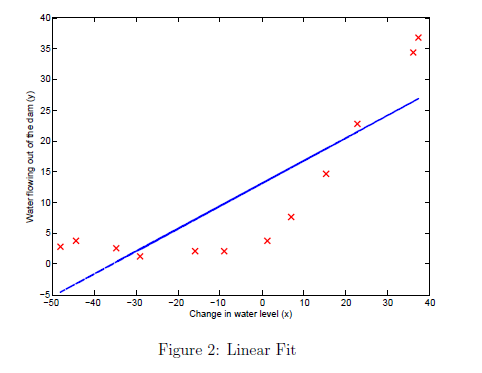

While visualizing the best fit as shown is one possible way to debug your learning algorithm, it is not always easy to visualize the data and model. In the next section, you will implement a function to generate learning curves that can help you debug your learning algorithm even if it is not easy to visualize the data.

## 2. Bias-variance

An important concept in machine learning is the bias-variance tradeoff. Models with high bias are not complex enough for the data and tend to underfit, while models with high variance overfit the training data. In this part of the exercise, you will plot training and test errors on a learning curve to diagnose bias-variance problems.

### 2.1 Learning curves

You will now implement code to generate the learning curves that will be useful in debugging learning algorithms. Recall that a learning curve plots training and cross validation error as a function of training set size. Your job is to fill in `learningCurve.m` so that it returns a vector of errors for the training set and cross validation set.

    To plot the learning curve, we need a training and cross validation set error for different training set sizes. To obtain different training set sizes, you should use different subsets of the original training set `X`. Specically, for a training set size of `i`, you should use the first `i` examples (i.e., `X(1:i,:) `and `y(1:i))`. You can use the `trainLinearReg` function to find the $\theta$ parameters. Note that `lambda` is passed as a parameter to the `learningCurve` function. After learning the $\theta$ parameters, you should compute the error on the training and cross validation sets. Recall that the training error for a dataset is defined as


$$J_{\mathrm{train}} \left(\theta \right)=\frac{1}{2m}\left\lbrack \sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \right\rbrack$$


    In particular, note that the training error does not include the regularization term. One way to compute the training error is to use your existing cost function and set $\lambda$ to 0 only when using it to compute the training error and cross validation error. When you are computing the training set error, make sure you compute it on the training subset (i.e., `X(1:n,:)` and `y(1:n)`, instead of the entire training set). However, for the cross validation error, you should compute it over the entire cross validation set. You should store the computed errors in the vectors `error_train` and `error_val`.  

    In Figure 3, you can observe that both the train error and cross validation error are high when the number of training examples is increased. This reflects a high bias problem in the model - the linear regression model is too simple and is unable to fit our dataset well. In the next section, you will implement polynomial regression to fit a better model for this dataset.

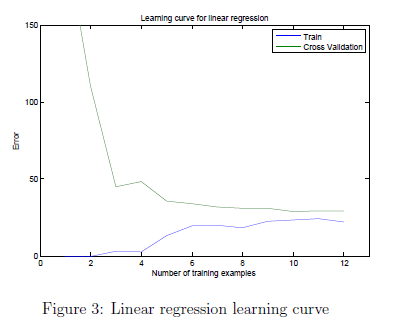

    When you are finished, run the code below to compute the learning curves and produce a plot similar to Figure 3.

lambda = 0;
[error_train, error_val] = learningCurve([ones(m, 1) X], y, [ones(size(Xval, 1), 1) Xval], yval, lambda);

plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])

fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');
for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

## 3. Polynomial regression

The problem with our linear model was that it was too simple for the data and resulted in underfitting (high bias). In this part of the exercise, you will address this problem by adding more features. For use polynomial regression, our hypothesis has the form:


$$h_\theta(x) =\theta_0+\theta_1\ast (waterLevel)+\theta_2*
(waterLevel)^2+\cdots+\theta_p\ast (waterLevel)^p \\
\qquad\;=\theta_0+\theta_1 x_1+\theta_2 x_2+\cdots+\theta_p x_p \end{aligned}$$


Notice that by defining $x_1 = (\text{waterLevel}), x_2 = (\text{waterLevel)}^2,\ldots,x_p = (\text{waterLevel})^p$, we obtain a linear regression model where the features are the various powers of the original value (*waterLevel*).

    Now, you will add more features using the higher powers of the existing feature $x$ in the dataset. Your task in this part is to complete the code in `polyFeatures.`m so that the function maps the original training set `X` of size $m\times 1$into its higher powers. Specifically, when a training set $X$ of size $m\times 1$ is passed into the function, the function should return a $m\times p$ matrix `X_poly`, where column 1 holds the original values of `X`, column 2 holds the values of `X.^2`, column 3 holds the values of `X.^3`, and so on. Note that you don't have to account for the zero-th power in this function. Now that you have a function that will map features to a higher dimension, the code in the next section will apply it to the training set, the test set, and the cross validation set (which you haven't used yet).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.1 Learning Polynomial Regression

After you have completed `polyFeatures.m`, run the code below to train polynomial regression using your linear regression cost function. Keep in mind that even though we have polynomial terms in our feature vector, we are still solving a linear regression optimization problem. The polynomial terms have simply turned into features that we can use for linear regression. We are using the same cost function and gradient that you wrote for the earlier part of this exercise.

    For this part of the exercise, you will be using a polynomial of degree 8. It turns out that if we run the training directly on the projected data, it will not work well as the features would be badly scaled (e.g., an example with $x = 40$ will now have a feature $x_8 = 40^8 = 6:5\times 10^{12$) Therefore, you will need to use feature normalization. Before learning the parameters $\theta$ for the polynomial regression, code in below will first call `featureNormalize` to normalize the features of the training set, storing the `mu`, `sigma` parameters separately. We have already implemented this function for you and it is the same function from the first exercise.

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% % Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = X_poly_test-mu; % uses implicit expansion instead of bsxfun
X_poly_test = X_poly_test./sigma; % uses implicit expansion instead of bsxfun
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = X_poly_val-mu; % uses implicit expansion instead of bsxfun
X_poly_val = X_poly_val./sigma; % uses implicit expansion instead of bsxfun
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');
fprintf('  %f  \n', X_poly(1, :));

lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

    After learning the parameters $\theta$, the code below will generate two plots (Figures 4,5) for polynomial regression with $\lambda = 0$. 

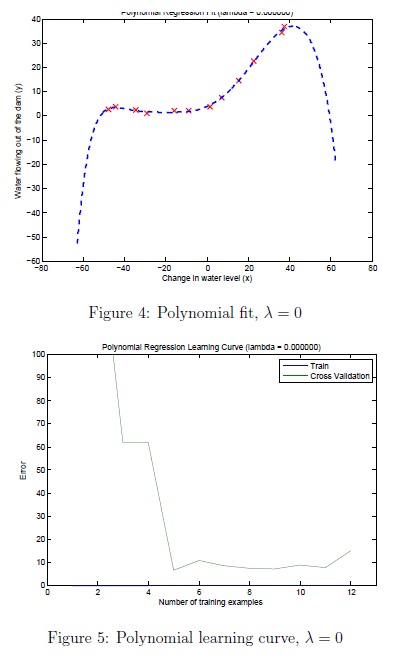

From Figure 4, you should see that the polynomial fit is able to follow the datapoints very well - thus, obtaining a low training error. However, the polynomial fit is very complex and even drops off at the extremes. This is an indicator that the polynomial regression model is overfitting the training data and will not generalize well.

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

    To better understand the problems with the unregularized $\lambda=0$ model, you can see that the learning curve (Figure 5) shows the same effect where the low training error is low, but the cross validation error is high. There is a gap between the training and cross validation errors, indicating a high variance problem. One way to combat the overfitting (high-variance) problem is to add regularization to the model. In the next section, you will get to try different $\lambda$ parameters to see how regularization can lead to a better model.

### 3.2 Optional (ungraded) exercise: Adjusting the regularization parameter

In this section, you will get to observe how the regularization parameter affects the bias-variance of regularized polynomial regression. You should now modify the the `lambda` parameter in the code below and try $\lambda = 1,\; 100$. 

% Choose the value of lambda
lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

% Plot training data and fit
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);
title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For each of these values, the code should generate a polynomial fit to the data and also a learning curve.

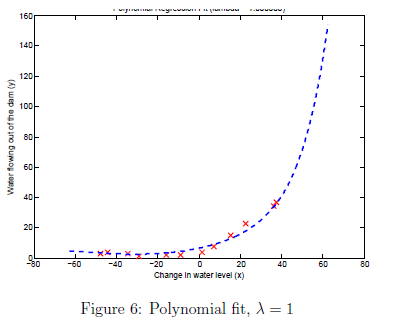

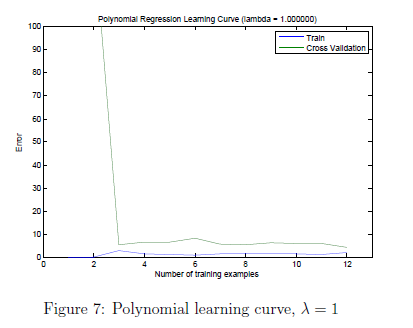

    For $\lambda= 1$, you should see a polynomial fit that follows the data trend well (Figure 6) and a learning curve (Figure 7) showing that both the cross validation and training error converge to a relatively low value. This shows the $\lambda= 1$ regularized polynomial regression model does not have the high bias or high-variance problems. In effect, it achieves a good trade-off between bias and variance.

    For $\lambda= 100$, you should see a polynomial fit (Figure 8) that does not follow the data well. In this case, there is too much regularization and the model is unable to fit the training data.

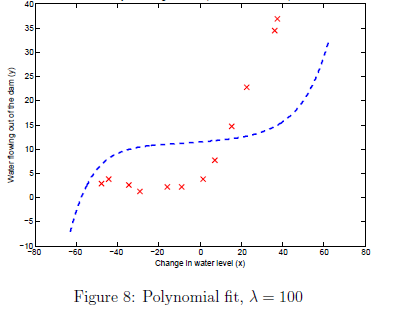

### 3.3 Selecting lambda using a cross validation set

From the previous parts of the exercise, you observed that the value of $\lambda$ can significantly affect the results of regularized polynomial regression on the training and cross validation set. In particular, a model without regularization ($\lambda = 0$) fits the training set well, but does not generalize. Conversely, a model with too much regularization ($\lambda=100$)  does not fit the training set and testing set well. A good choice of $\lambda$ (e.g. $\lambda=1$) can provide a good fit to the data.

    In this section, you will implement an automated method to select the parameter. Concretely, you will use a cross validation set to evaluate how good each $\lambda$ value is. After selecting the best $\lambda$ value using the cross validation set, we can then evaluate the model on the test set to estimate how well the model will perform on actual unseen data. Your task is to complete the code in `validationCurve.m`. Specifically, you should should use the `trainLinearReg` function to train the model using different values of $\lambda$ and compute the training error and cross validation error. The function will try $\lambda$ in the following range: {0, 0.001, 0.003, 0.01, 0.03, 0.1, 0.3, 1, 3, 10}.

    After you have completed the code, the code below will run your function and plot a cross validation curve of error v.s $\lambda$ that allows you select which $\lambda$ parameter to use. You should see a plot similar to Figure 9. 

[lambda_vec, error_train, error_val] = validationCurve(X_poly, y, X_poly_val, yval);
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');
for i = 1:length(lambda_vec)
    if i == 1
        fprintf('lambda\t\tTrain Error\tValidation Error\n');
    end
    fprintf('%f\t%f\t%f\n',lambda_vec(i), error_train(i), error_val(i));
end

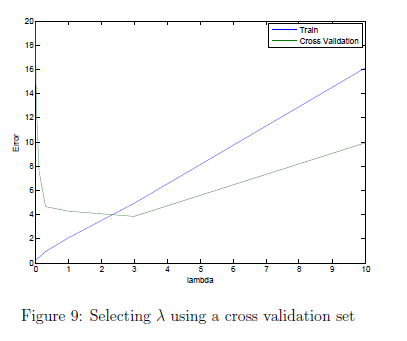

In this figure, we can see that the best value of $\lambda$ is around 3. Due to randomness in the training and validation splits of the dataset, the cross validation error can sometimes be lower than the training error. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 3.4 Optional (ungraded) exercise: Computing test set error

In the previous part of the exercise, you implemented code to compute the cross validation error for various values of the regularization parameter $\lambda$. However, to get a better indication of the model's performance in the real world, it is important to evaluate the 'final' model on a test set that was not used in any part of training (that is, it was neither used to select the $\lambda$ parameters, nor to learn the model parameters $\theta$).

    For this optional (ungraded) exercise, you should compute the test error using the best value of $\lambda$ you found. In our cross validation, we obtained a test error of 3.8599 for $\lambda= 3.$ You do not need to submit any solutions for this optional (ungraded) exercise.

%%%%%%%%% Add your code to compute the test error below %%%%%%%%%%%



### 3.5 Optional (ungraded) exercise: Plotting learning curves with randomly selected examples

In practice, especially for small training sets, when you plot learning curves to debug your algorithms, it is often helpful to average across multiple sets of randomly selected examples to determine the training error and cross validation error. Concretely, to determine the training error and cross validation error for $i$ examples, you should first randomly select $i$ examples from the training set and $i$ examples from the cross validation set. You will then learn the parameters $\theta$ using the randomly chosen training set and evaluate the parameters $\theta$ on the randomly chosen training set and cross validation set. The above steps should then be repeated multiple times (say 50) and the averaged error should be used to determine the training error and cross validation error for $i$ examples.

     For this optional (ungraded) exercise, you should implement the above strategy for computing the learning curves in `learningCurve.m` and use the code below to call your modified function and generate the plot.

lambda = 0.01;
[error_train, error_val] = learningCurve(X_poly, y, X_poly_val, yval, lambda);
plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')

For reference, Figure 10 shows the learning curve we obtained for polynomial regression with $\lambda= 0.01$. 

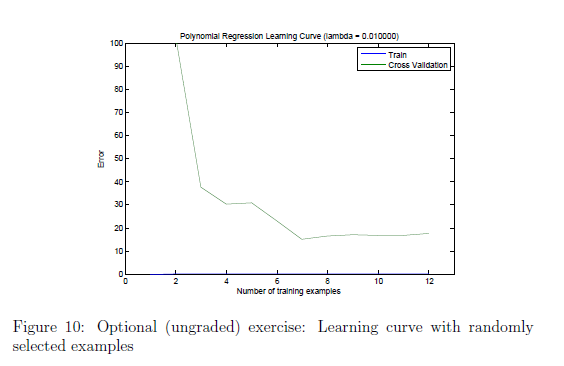

Your figure may differ slightly due to the random selection of examples. 

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

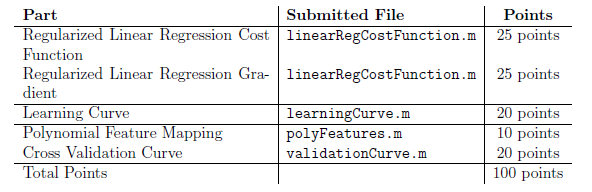

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

.                        ex5data1.mat             lib                      submit.m                 
..                       featureNormalize.m       linearRegCostFunction.m  trainLinearReg.m         
ex5.mlx                  fmincg.m                 plotFit.m                validationCurve.m        
ex5_companion.mlx        learningCurve.m          polyFeatures.m           

